### Title of the experiment

- a

- few

- objectives

First, read in a dataset:

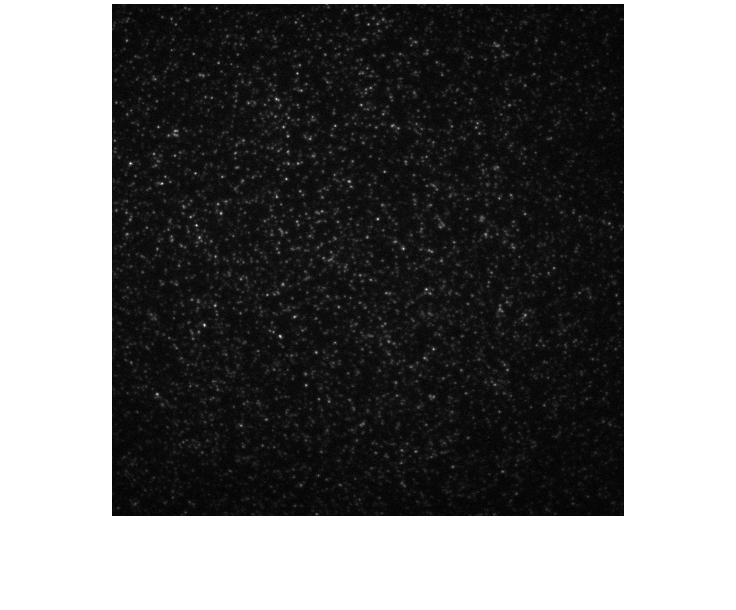

% read in first frame of a video
% display
% use control tool to scrub through frames?
frame = imread("Cy5DNA_A565_6xG_pos_2xwash_002.tif","tif","Index",13);
imshow(frame,[]);

Next, apply a gaussian blurring filter and subtract the background:

% perform gaussian smoothing
% subtract background
% display
sigma = 16;
gaussian = imgaussfilt(frame,sigma);
imshow(gaussian,[]);

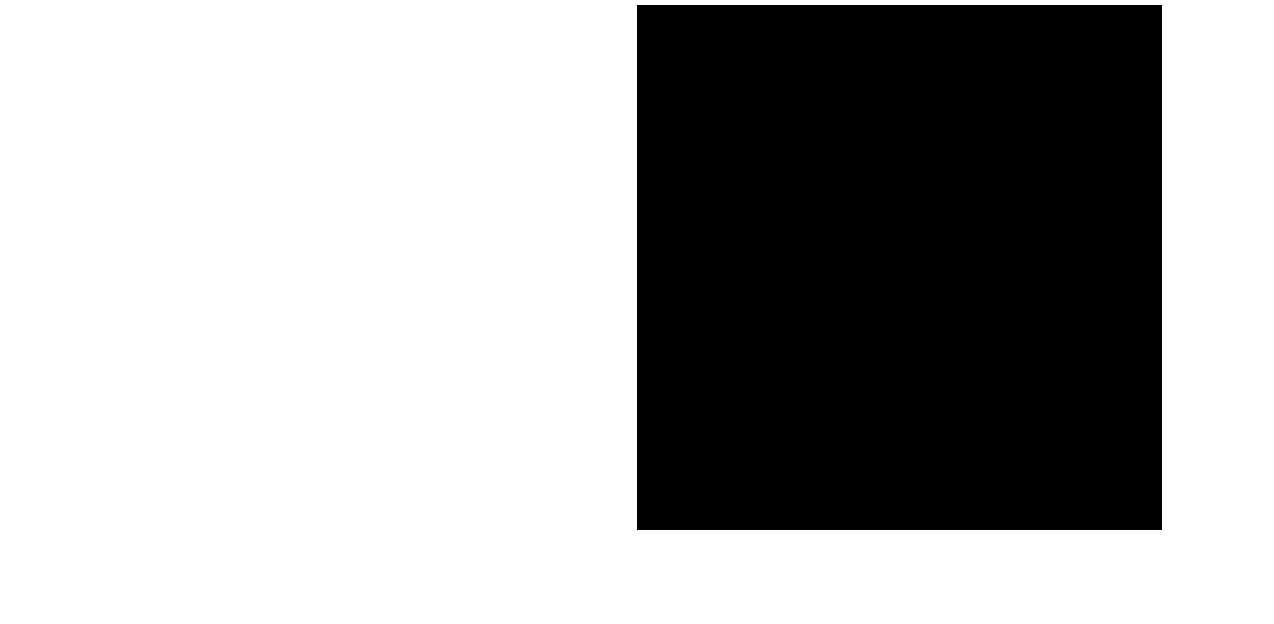

background_subtracted = frame-gaussian;
montage({frame,background_subtracted},'DisplayRange',[]);

Refactor!

video = testfxn("Cy5DNA_A565_6xG_pos_2xwash_002.tif",100,16);

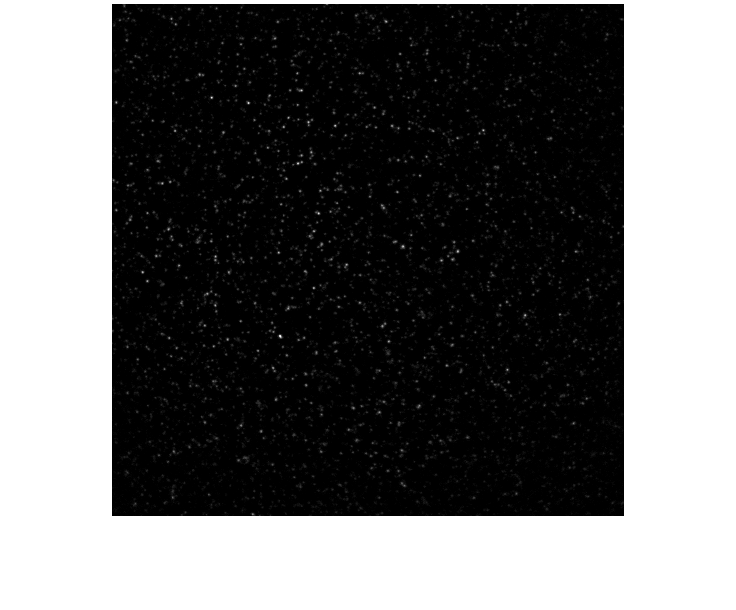

imshow(video(:,:,67),[]);